%This livescript intend to visualize the sampling of the tstat and ß
%images. The script works with the output of the sampling function
%BK_layer_sampling_pain_study_pipeline (see the function how to call)

% figure('Position',[100, 100, 2400, 1200]);
plotidx=0;
allsubj={7349, 7356, 7361, 7375, 7376,...
         7383, 7402, 7403, 7404,...
         7405, 7408, 7414, 7415,...
         7425, 7426, 7433, 7434,...
         7435, 7443, 7444, 7445,...
         7448, 7449, 7452, 7453,...
         7454, 7455, 7456, 7457,...
         7468, 7469, 7482, 7484, 7485}; %34subj 7349 output was too big-->not safed and need to rerun, and 7356 has no good orientation was not run at all.32 is visualized now
% subjready={7403,7404,7444, 7484}
% subjready={7375, 7361, 7376,7383, 7402, 7403, 7404,7405, 7408, 7414, 7415};
subplotsize=[8 4];
% disp('This is the distribution of the indiviudal T value(across columns) for the three contrast')
allsubjlayer={};
subjidx=0;
td=[];
bu=[];
topdown=cell(2,1);
bottomup=cell(2,1);
for subj=allsubj%{7414,7482,7484,7485}
    roipath='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\';
    processedimgfile=[roipath num2str(subj{:}) '\functionalmasks\interimdata_rwls_pInsderived.mat'];
    %it has the follwoing output:
    %{1,1} cell: 2 cells, each for one side(left+right): vertex*image of the "columnarvalue"(deeper 75% of the column mean) 
    %{1,2} cell: 2 cells, each for one side(left+right): vertex*layer*image of the laminar value
    %{1,3} cell: 2 cells,each for one side(left+right): the depth of each "column"
    %{1,4} cell: the list of sampled images 
    if exist(processedimgfile,"file")
        processedimg=load(processedimgfile);
%         [columnspecificts,layeractivation,allroicolumnsize,sampled_img_list]
        disp([num2str(subj{:}) ' subject columnar info r'])
        nROI=length(processedimg.interimdata_columns{1,1});
        tthrs=1;
        topcolumnnumber=200; %200 or 100?
        subjidx=subjidx+1;
        plotidx=plotidx+1;
        allsubjid(plotidx)=subj{:};
        for ROI=1:nROI
            %based on t value
%             conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,3)*(-1),processedimg.interimdata_columns{1,1}{ROI,1}(:,4)],[],2); %3-cognition but need to be reversed!!,4-pain
            %based on ßmap
            conjugationcolumnarstat=min([processedimg.interimdata_columns{1,1}{ROI,1}(:,1)*(-1),processedimg.interimdata_columns{1,1}{ROI,1}(:,2)],[],2); %3-cognition but need to be reversed!!,4-pain
            
            
            numberofcolumnsinmask=length(conjugationcolumnarstat);
                    
            numberofactcolumnsbasedonconj=sum(conjugationcolumnarstat>tthrs);
                    
            disp(['Subject:' subj{:} 'The number of columns within the funcitonal mask: ',num2str(numberofcolumnsinmask)])
            
            disp(['Subject:' subj{:} 'The number of columns acitvating in each run(t>', num2str(tthrs), ') for cognition AND pain: ',num2str(numberofactcolumnsbasedonconj)])

            [top200Values, top200Indices] =maxk(conjugationcolumnarstat,topcolumnnumber);
            positiveIndices = top200Indices(top200Values > 0);
            % Check if any negative values were removed
            if length(positiveIndices) < topcolumnnumber
                warning('The top 200 values contained negative numbers. Only %d positive values are retained.', length(positiveIndices));
            end
%             subj_td=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,1)*(-1),1,'omitnan');%main effect of cognition but need to be reversed!!!;
%             subj_bu=mean(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,2),1,'omitnan'); %main effect of pain

            %median
            subj_td=median(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,1)*(-1),1,'omitnan');%main effect of cognition but need to be reversed!!!;
            subj_bu=median(processedimg.interimdata_columns{1,2}{ROI,1}(positiveIndices,:,2),1,'omitnan'); %main effect of pain

            topdown{ROI}=vertcat(topdown{ROI},subj_td);
%             td=topdown{ROI};
            bottomup{ROI}=vertcat(bottomup{ROI},subj_bu);
%             bu=bottomup{ROI};
        end 
    else
        disp([num2str(subj{:}) ' subject has  no sampled cluster'])
    end

end

7349 subject has  no sampled cluster
7356 subject has  no sampled cluster


7361 subject columnar info r


Subject:᳁The number of columns within the funcitonal mask: 1793


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 174


Subject:᳁The number of columns within the funcitonal mask: 1236


Subject:᳁The number of columns acitvating in each run(t>1) for cognition AND pain: 84


7375 subject columnar info r


Subject:᳏The number of columns within the funcitonal mask: 1567


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 101


Subject:᳏The number of columns within the funcitonal mask: 1276


Subject:᳏The number of columns acitvating in each run(t>1) for cognition AND pain: 115


7376 subject columnar info r


Subject:᳐The number of columns within the funcitonal mask: 1467


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 108


Subject:᳐The number of columns within the funcitonal mask: 1369


Subject:᳐The number of columns acitvating in each run(t>1) for cognition AND pain: 99


7383 subject columnar info r


Subject:᳗The number of columns within the funcitonal mask: 1651


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 201


Subject:᳗The number of columns within the funcitonal mask: 1138


Subject:᳗The number of columns acitvating in each run(t>1) for cognition AND pain: 165


7402 subject columnar info r


Subject:ᳪThe number of columns within the funcitonal mask: 3216


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 394


Subject:ᳪThe number of columns within the funcitonal mask: 2785


Subject:ᳪThe number of columns acitvating in each run(t>1) for cognition AND pain: 387


7403 subject columnar info r


Subject:ᳫThe number of columns within the funcitonal mask: 1127


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 89


Subject:ᳫThe number of columns within the funcitonal mask: 1163


Subject:ᳫThe number of columns acitvating in each run(t>1) for cognition AND pain: 113


7404 subject columnar info r


Subject:ᳬThe number of columns within the funcitonal mask: 1474


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 128


Subject:ᳬThe number of columns within the funcitonal mask: 1231


Subject:ᳬThe number of columns acitvating in each run(t>1) for cognition AND pain: 82


7405 subject columnar info r


Subject:᳭The number of columns within the funcitonal mask: 1082


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 95


Subject:᳭The number of columns within the funcitonal mask: 1181


Subject:᳭The number of columns acitvating in each run(t>1) for cognition AND pain: 186


7408 subject columnar info r


Subject:ᳰThe number of columns within the funcitonal mask: 1414


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 112


Subject:ᳰThe number of columns within the funcitonal mask: 1277


Subject:ᳰThe number of columns acitvating in each run(t>1) for cognition AND pain: 142


7414 subject columnar info r


Subject:ᳶThe number of columns within the funcitonal mask: 1272


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 175


Subject:ᳶThe number of columns within the funcitonal mask: 1268


Subject:ᳶThe number of columns acitvating in each run(t>1) for cognition AND pain: 239


7415 subject columnar info r


Subject:᳷The number of columns within the funcitonal mask: 1196


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 42


Subject:᳷The number of columns within the funcitonal mask: 1232


Subject:᳷The number of columns acitvating in each run(t>1) for cognition AND pain: 91


7425 subject columnar info r


Subject:ᴁThe number of columns within the funcitonal mask: 1450


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 60


Subject:ᴁThe number of columns within the funcitonal mask: 1389


Subject:ᴁThe number of columns acitvating in each run(t>1) for cognition AND pain: 59


7426 subject columnar info r


Subject:ᴂThe number of columns within the funcitonal mask: 1218


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 159


Subject:ᴂThe number of columns within the funcitonal mask: 1280


Subject:ᴂThe number of columns acitvating in each run(t>1) for cognition AND pain: 161


7433 subject columnar info r


Subject:ᴉThe number of columns within the funcitonal mask: 1970


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 103


Subject:ᴉThe number of columns within the funcitonal mask: 1589


Subject:ᴉThe number of columns acitvating in each run(t>1) for cognition AND pain: 131


7434 subject columnar info r


Subject:ᴊThe number of columns within the funcitonal mask: 1471


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 182


Subject:ᴊThe number of columns within the funcitonal mask: 1301


Subject:ᴊThe number of columns acitvating in each run(t>1) for cognition AND pain: 170


7435 subject columnar info r


Subject:ᴋThe number of columns within the funcitonal mask: 1210


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 120


Subject:ᴋThe number of columns within the funcitonal mask: 1122


Subject:ᴋThe number of columns acitvating in each run(t>1) for cognition AND pain: 88


7443 subject columnar info r


Subject:ᴓThe number of columns within the funcitonal mask: 2234


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 224


Subject:ᴓThe number of columns within the funcitonal mask: 1557


Subject:ᴓThe number of columns acitvating in each run(t>1) for cognition AND pain: 125


7444 subject columnar info r


Subject:ᴔThe number of columns within the funcitonal mask: 1748


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 165


Subject:ᴔThe number of columns within the funcitonal mask: 1737


Subject:ᴔThe number of columns acitvating in each run(t>1) for cognition AND pain: 349


7445 subject columnar info r


Subject:ᴕThe number of columns within the funcitonal mask: 1332


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 124


Subject:ᴕThe number of columns within the funcitonal mask: 1522


Subject:ᴕThe number of columns acitvating in each run(t>1) for cognition AND pain: 223


7448 subject columnar info r


Subject:ᴘThe number of columns within the funcitonal mask: 1347


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 220


Subject:ᴘThe number of columns within the funcitonal mask: 1160


Subject:ᴘThe number of columns acitvating in each run(t>1) for cognition AND pain: 171


7449 subject columnar info r


Subject:ᴙThe number of columns within the funcitonal mask: 1603


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 120


Subject:ᴙThe number of columns within the funcitonal mask: 1579


Subject:ᴙThe number of columns acitvating in each run(t>1) for cognition AND pain: 133


7452 subject columnar info r


Subject:ᴜThe number of columns within the funcitonal mask: 1266


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 92


Subject:ᴜThe number of columns within the funcitonal mask: 1107


Subject:ᴜThe number of columns acitvating in each run(t>1) for cognition AND pain: 118


7453 subject columnar info r


Subject:ᴝThe number of columns within the funcitonal mask: 1318


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 144


Subject:ᴝThe number of columns within the funcitonal mask: 1404


Subject:ᴝThe number of columns acitvating in each run(t>1) for cognition AND pain: 142


7454 subject columnar info r


Subject:ᴞThe number of columns within the funcitonal mask: 1299


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 206


Subject:ᴞThe number of columns within the funcitonal mask: 1150


Subject:ᴞThe number of columns acitvating in each run(t>1) for cognition AND pain: 130


7455 subject columnar info r


Subject:ᴟThe number of columns within the funcitonal mask: 1245


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 153


Subject:ᴟThe number of columns within the funcitonal mask: 1014


Subject:ᴟThe number of columns acitvating in each run(t>1) for cognition AND pain: 122


7456 subject columnar info r


Subject:ᴠThe number of columns within the funcitonal mask: 1241


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 150


Subject:ᴠThe number of columns within the funcitonal mask: 1157


Subject:ᴠThe number of columns acitvating in each run(t>1) for cognition AND pain: 114


7457 subject columnar info r


Subject:ᴡThe number of columns within the funcitonal mask: 1463


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 134


Subject:ᴡThe number of columns within the funcitonal mask: 1322


Subject:ᴡThe number of columns acitvating in each run(t>1) for cognition AND pain: 138


7468 subject columnar info r


Subject:ᴬThe number of columns within the funcitonal mask: 1160


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 65


Subject:ᴬThe number of columns within the funcitonal mask: 1103


Subject:ᴬThe number of columns acitvating in each run(t>1) for cognition AND pain: 101


7469 subject columnar info r


Subject:ᴭThe number of columns within the funcitonal mask: 1544


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 132


Subject:ᴭThe number of columns within the funcitonal mask: 1268


Subject:ᴭThe number of columns acitvating in each run(t>1) for cognition AND pain: 138


7482 subject columnar info r


Subject:ᴺThe number of columns within the funcitonal mask: 1440


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 139


Subject:ᴺThe number of columns within the funcitonal mask: 1299


Subject:ᴺThe number of columns acitvating in each run(t>1) for cognition AND pain: 127


7484 subject columnar info r


Subject:ᴼThe number of columns within the funcitonal mask: 1145


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 190


Subject:ᴼThe number of columns within the funcitonal mask: 1161


Subject:ᴼThe number of columns acitvating in each run(t>1) for cognition AND pain: 160


7485 subject columnar info r


Subject:ᴽThe number of columns within the funcitonal mask: 1251


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 161


Subject:ᴽThe number of columns within the funcitonal mask: 1262


Subject:ᴽThe number of columns acitvating in each run(t>1) for cognition AND pain: 165


nproc=2;
nsubj=length(allsubjid);
nside=2;

td=array2table([topdown{1};topdown{2}],'VariableNames',strcat("layer",string(1:20)));
td.process=repmat("topdown",nsubj*nside,1);
td.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

bu=array2table([bottomup{1};bottomup{2}],'VariableNames',strcat("layer",string(1:20)));
bu.process=repmat("bottomup",nsubj*nside,1);
bu.side=[repmat("left",nsubj,1);repmat("right",nsubj,1)];

pIns=[td;bu];

pIns.subjid=string(repmat(allsubjid',nproc*nside,1));
% s1.subjid=string(repmat(allsubjid',nproc,1));
pathtooutput='C:\Users\lenov\Documents\layerfMRI_DATA\groupavg_correctBET\layerdata\';

writetable(pIns,[ pathtooutput 'pIns_derived_layervalues.csv'])
% writematrix(allsubjid',[pathtooutput 'S1_subjid.csv'])


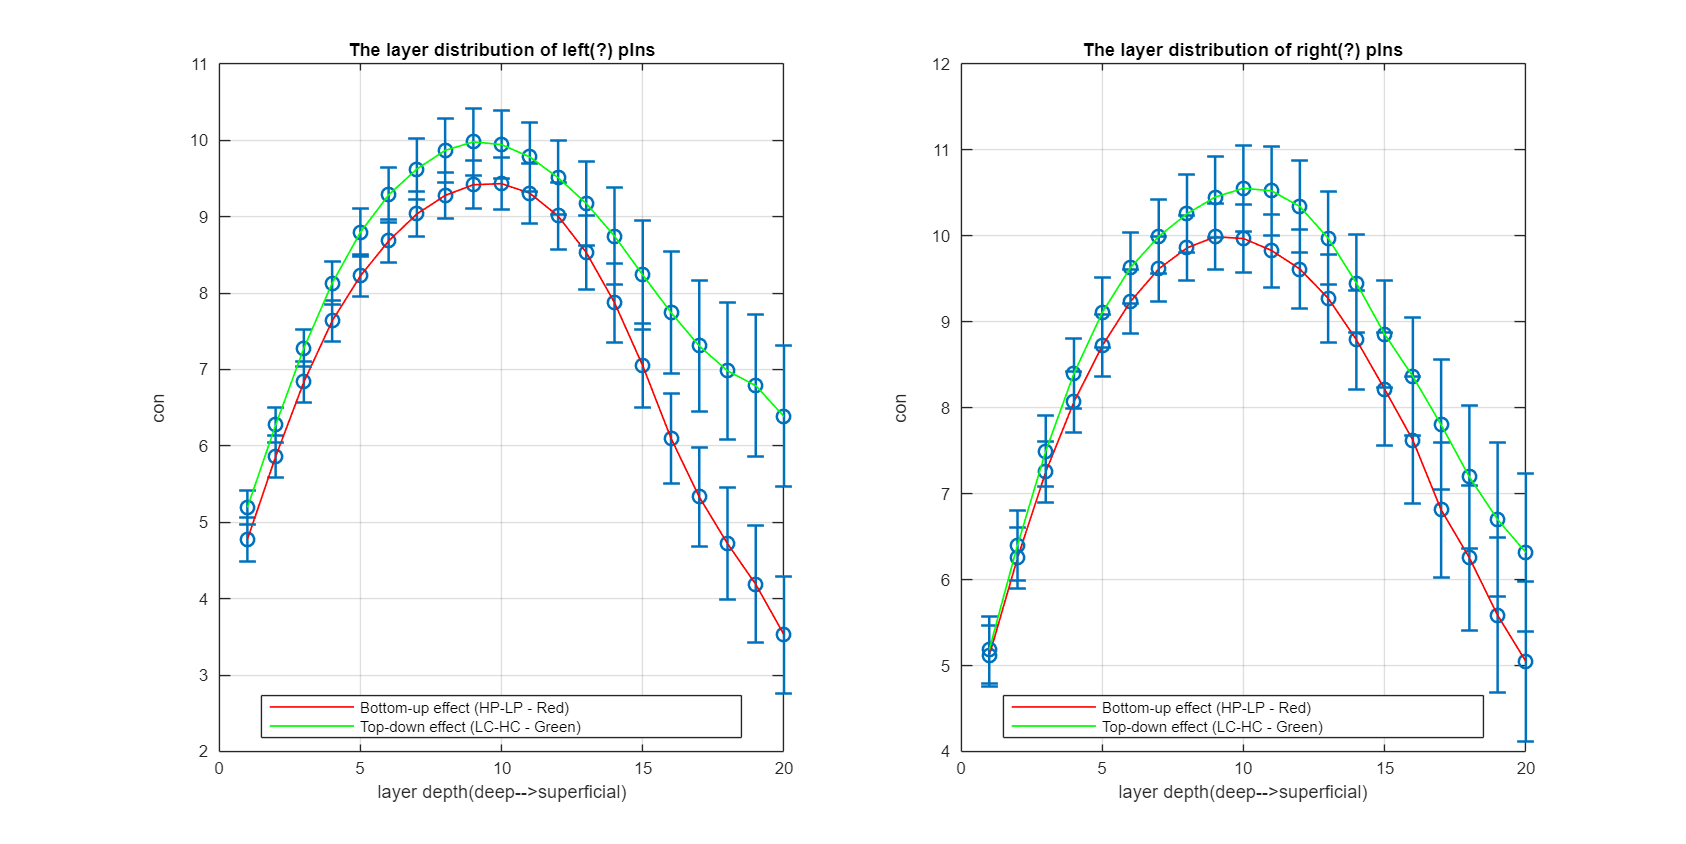

figure('Position',[100, 100, 2400, 1200]);

% alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottomup{roitype,1}, topdown{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) pIns';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) pIns';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end

figure('Position',[100, 100, 2400, 1200]);
disp('This is the median distribution')

This is the median distribution


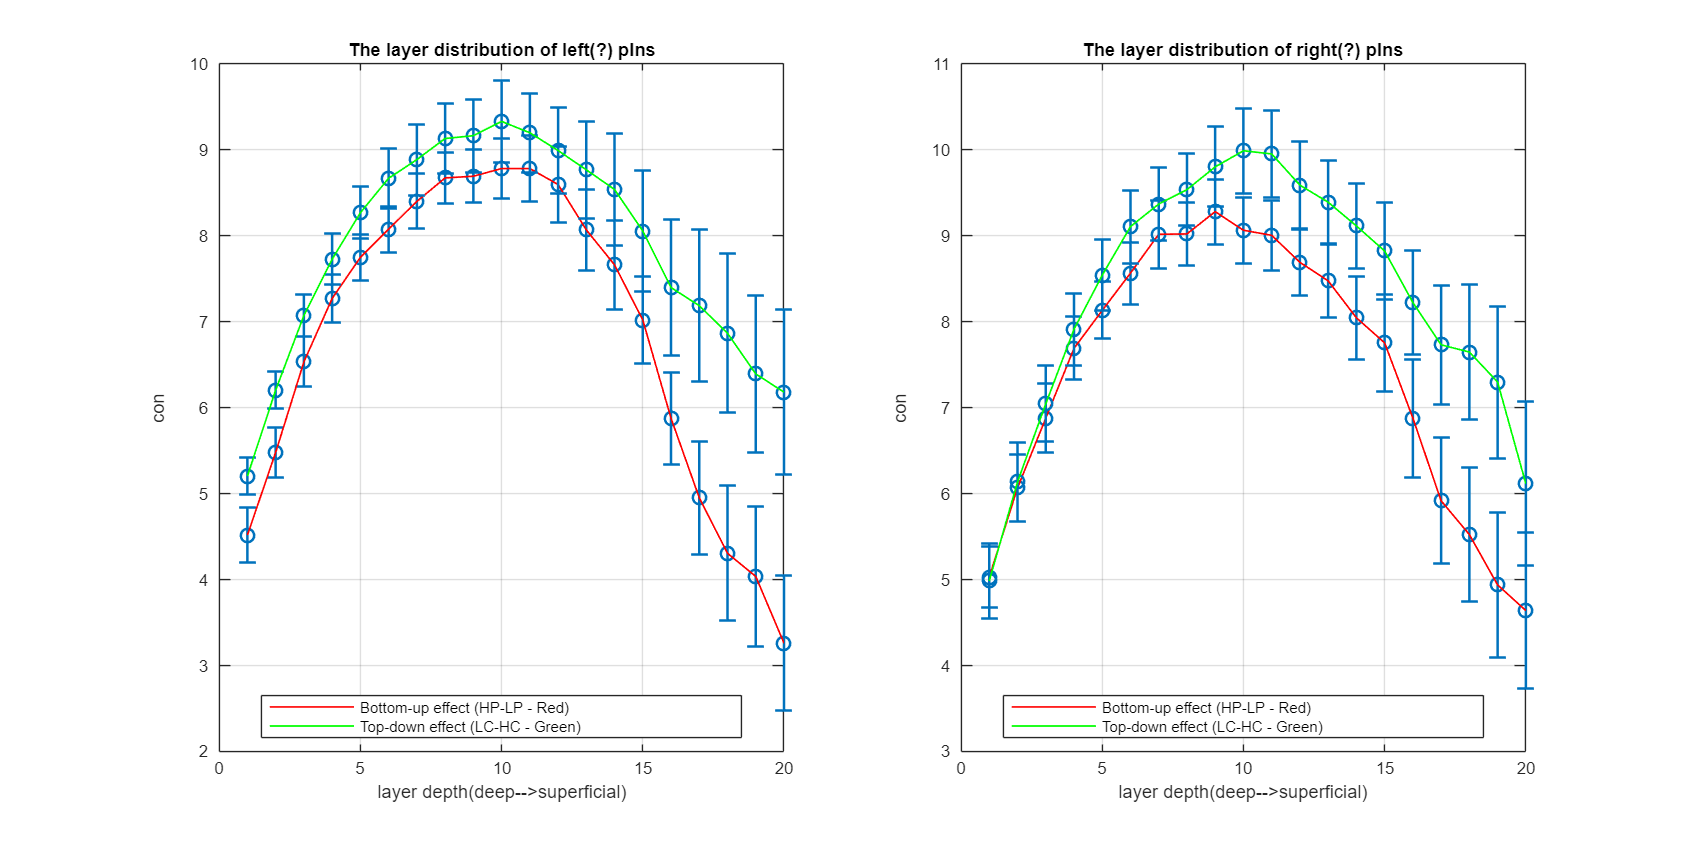

% alldataroi2_bet={bottomup_t,topdown_t};
for roitype=1:2
    alldata={bottomup{roitype,1}, topdown{roitype,1}};
    if roitype==1
    %             data=alldataroi1_beta{dataidx};
        titlenm='The layer distribution of left(?) pIns';
        
    elseif roitype==2
    %             data=alldataroi2_bet{dataidx};
        titlenm='The layer distribution of right(?) pIns';
        
    end
    for dataidx=1:2
        % Calculate column-wise mean and standard error

        data=alldata{dataidx};
        ylabltxt='con';
        columnMeans = mean(data, 1); % Mean of each column
        columnStdErrors = std(data, 0, 1) ./ sqrt(size(data, 1)); % Standard error
        subplot(1,2,roitype)
        % Create the scatter plot
%         legend('Bottom-up affect (main eff of pain - Red)','Top-down (main effect of cognition - Blue)', 'Location', 'south');

        errorbar(1:20, columnMeans, columnStdErrors, ...
            'o', 'LineWidth', 1.5, 'MarkerSize', 8, 'Color', [0 0.4470 0.7410], 'CapSize', 10);
        hold on;
        
        % Connect the points with a line
        if dataidx==1
            lineHandle1 = plot(1:20, columnMeans, '-r', 'LineWidth', 1);
        else
            lineHandle2 = plot(1:20, columnMeans, '-g', 'LineWidth', 1);
        end

        % Customize the plot
        xlabel('layer depth(deep-->superficial)');
        ylabel(ylabltxt);
        % Add legend only for the lines
        
    %     label()
        title(titlenm);
        grid on;
        
    end
    legend([lineHandle1, lineHandle2], ...
        {'Bottom-up effect (HP-LP - Red)', ...
        'Top-down effect (LC-HC - Green)'}, ...
        'Location', 'south');
    hold off;
end